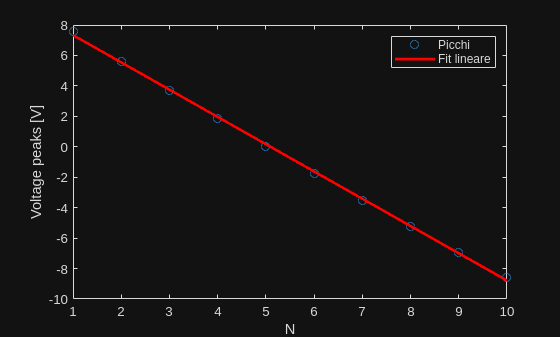

% Caricamento dati
data = readmatrix("dati_Rb.txt");
Vcount = data(:,1);
S_Rb   = -data(:,2);   % inverti il segnale
S_FP   = data(:,3);

% Trova picchi
[PKS,LOCS] = findpeaks(S_FP, 'MinPeakHeight', 0.2);
y = Vcount(LOCS);      % ascisse dei picchi
NN = 1:length(PKS);    % numeri dei picchi

% Fit lineare dei picchi
myfun = @(p,x) p(1) + p(2)*x;
beta0 = [1,-1];
beta = nlinfit(NN, y', myfun, beta0);

% Visualizza fit lineare
NNN = linspace(min(NN), max(NN), 1000);
figure;
plot(NN, y, 'o'); hold on;
plot(NNN, myfun(beta,NNN), 'r-', 'LineWidth', 2);
xlabel('N');
ylabel('Voltage peaks [V]');
legend('Picchi', 'Fit lineare');
hold off;

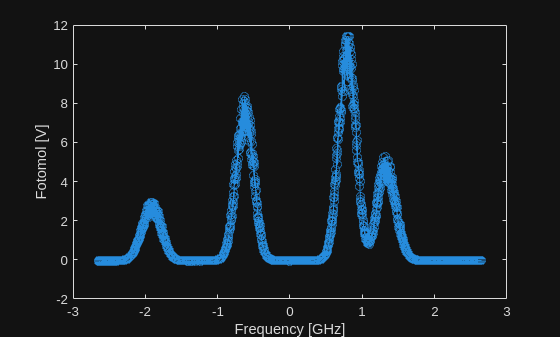


% Calcola frequenze
freq = 0.5*Vcount/beta(2);

% Plot dati S_Rb vs freq
figure;
plot(freq, S_Rb, '-o');
xlabel('Frequency [GHz]');
ylabel('Fotomol [V]');

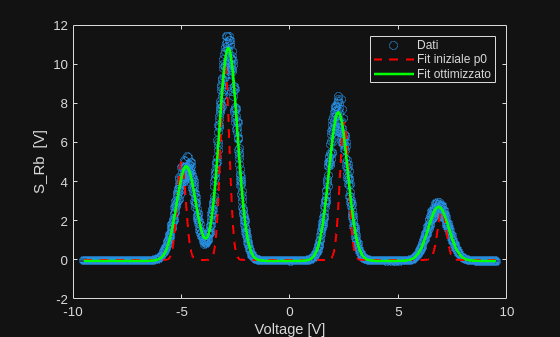


% Fit gaussiano multiplo
gauss = @(p,x) ...
    p(1)*exp(-0.5*((x-p(2))./p(3)).^2) + ...
    p(4)*exp(-0.5*((x-p(5))./p(6)).^2) + ...
    p(7)*exp(-0.5*((x-p(8))./p(9)).^2) + ...
    p(10)*exp(-0.5*((x-p(11))./p(12)).^2) + ...
    p(13);

gauss_col = @(p,x) gauss(p,x(:));


p0 = [5,-5,0.2, 10,-3,0.2, 7,2.5,0.2, 2.5,7,0.2, 0];

popt = nlinfit(Vcount, S_Rb, gauss, p0);

xx = linspace(min(Vcount), max(Vcount), 1000);
yy_initial = gauss(p0, xx);

yy_fit = gauss(popt, xx);

figure;
plot(Vcount, S_Rb, 'o'); hold on;
plot(xx, yy_initial, 'r--', 'LineWidth', 1.5); % fit iniziale
plot(xx, yy_fit, 'g-', 'LineWidth', 2);        % fit finale
xlabel('Voltage [V]');
ylabel('S\_Rb [V]');
legend('Dati', 'Fit iniziale p0', 'Fit ottimizzato');
hold off;